# LTE Scheduling Evaluation

## Initialization

Initialize parameters.

% Number of users array
% numUsersArray = [4, 8, 12, 16]; 
numUsersArray = [8, 16, 24, 32];  

% Number of 10ms Frames for simulation
numFrameSimulation = 10;  

% Calculate the simulation duration in seconds
simulationTime = numFrameSimulation * 1e-2;

% RR and PF schedulers for simulation and evaluation
schedulers = ["RoundRobin", "ProportionalFair"];

% Store Throughput and Fairness metrics
allThroughputs(length(numUsersArray)) = struct('RoundRobin', [], 'ProportionalFair', []);
allFairness(length(numUsersArray)) = struct('RoundRobin', [], 'ProportionalFair', []);

## Run Simulations

Configure the network for each experiment.

Run for each sceduler as many simulations as the number of different user values.

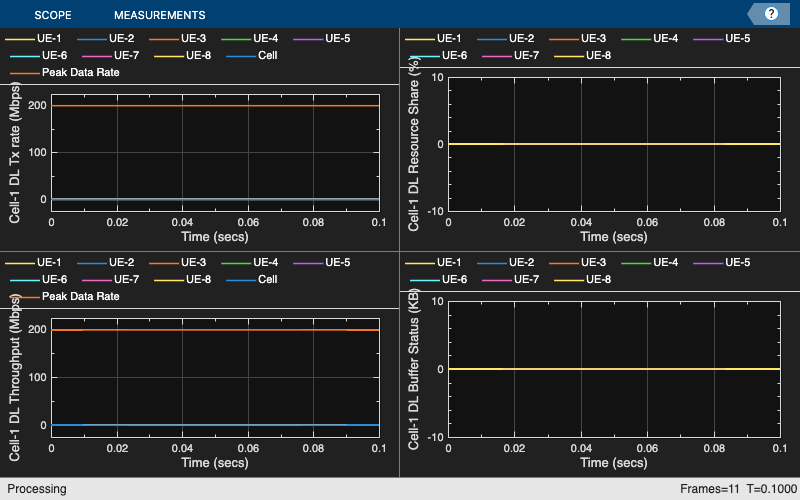

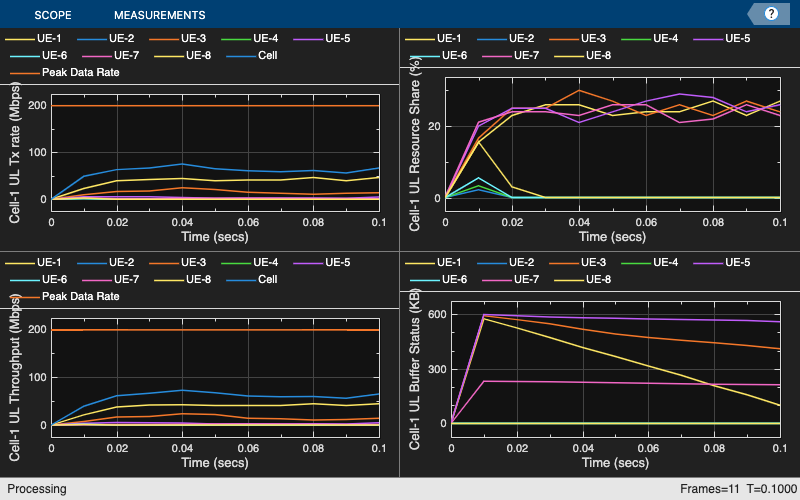

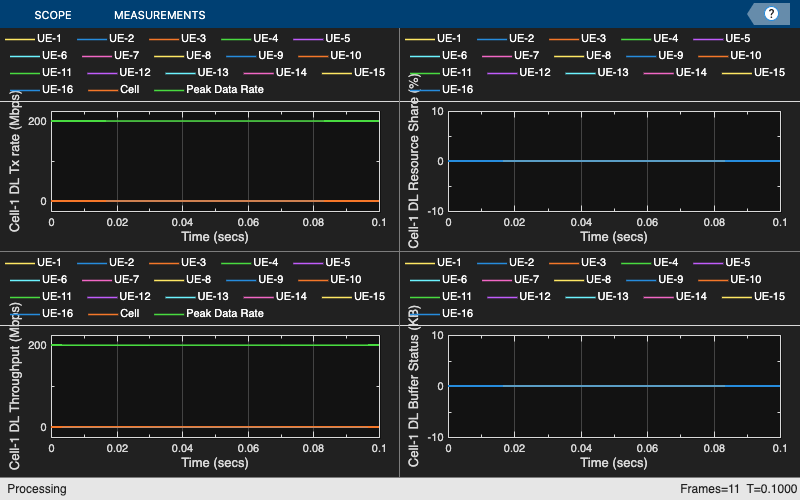

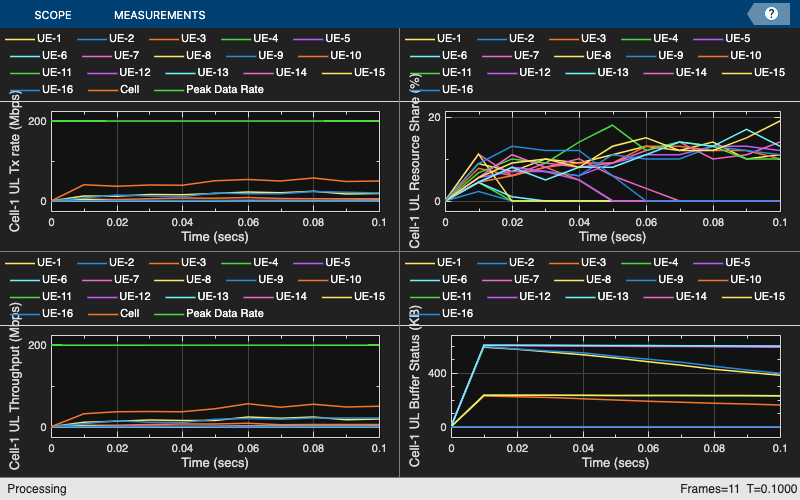

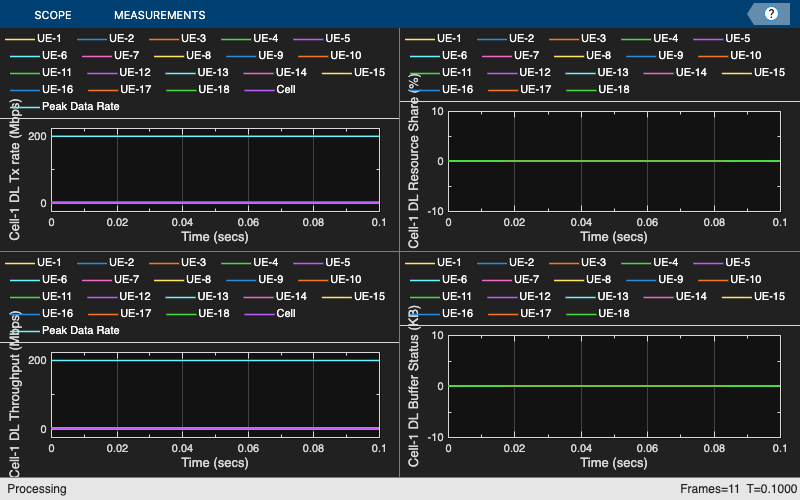

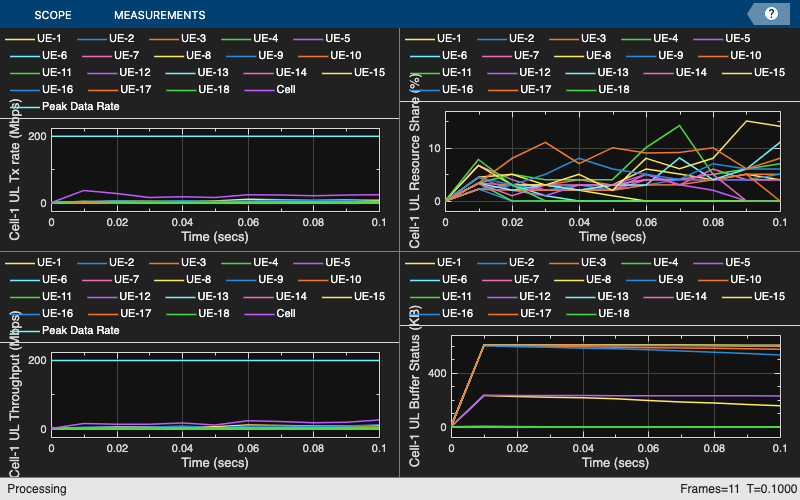

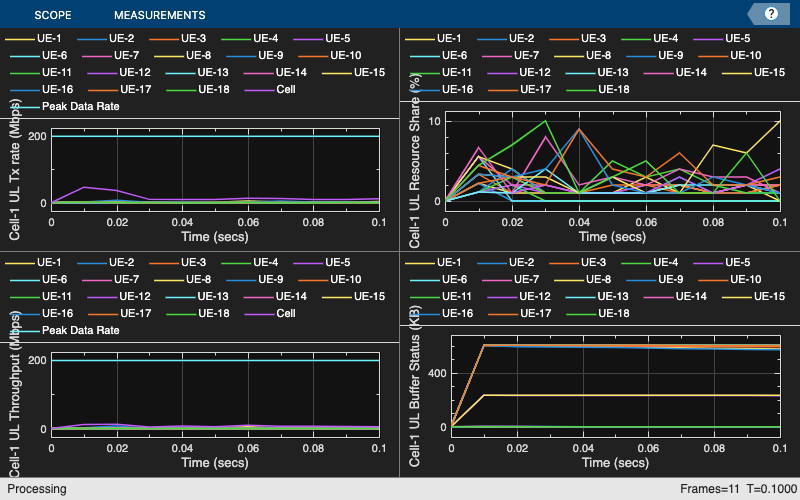

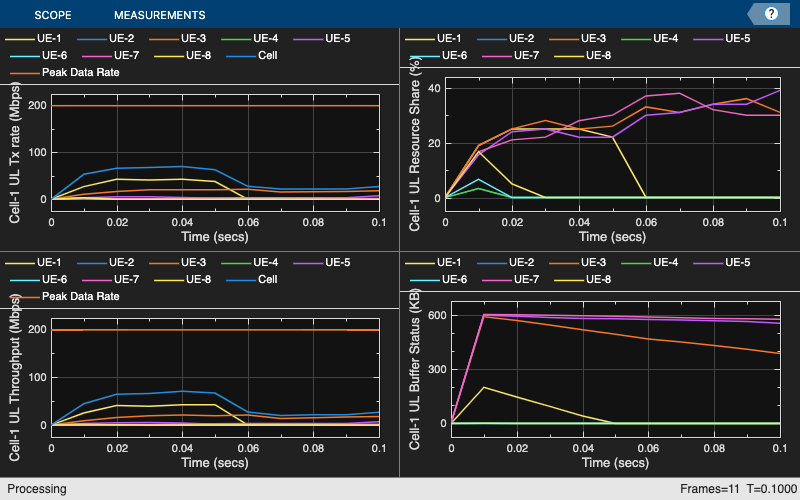

% Initialize the random number generator using the default algorithm and
% seed
rng('default');
for scheduler = schedulers
    for numUsers = numUsersArray
        % Store index of user number in the numUsersArray to use later on
        index = find(numUsersArray == numUsers);
        

        % Initialize wireless network simulator
        networkSimulator = wirelessNetworkSimulator.init;
    
        % Configure gNB
        gNB = nrGNB(Position=[0 0 30], DuplexMode="FDD", CarrierFrequency=2.6e9, ...
            ChannelBandwidth=30e6, SubcarrierSpacing=15e3, ReceiveGain=11);
        
        % Select scheduler for the simulation
        configureScheduler(gNB, Scheduler=scheduler, ResourceAllocationType=0);
    
        % Dynamically generate user positions and names
        uePositions = zeros(numUsers, 3);  % Preallocate array for positions

        for i = 1:numUsers
            uePositions(i, :) = [100 * i, 0, 3]; % Space users in x-axis
        end
    
        ueNames = "UE-" + (1:numUsers); % Dynamic user names
    
        % Struct to store UEs 
        UEs = nrUE(Name=ueNames, Position=uePositions, ReceiveGain=11);
    
        % Connect UEs to gNB
        connectUE(gNB, UEs)

        % Assign to half of the UEs VOIP applications and to the other half
        % FTP applications
        for ueIdx =  1:numUsers
            if mod(ueIdx, 2) == 0   % If ueIdx is even add VOIP traffic
                onoffTraffic = networkTrafficOnOff(GeneratePacket=true);
                addTrafficSource(UEs(ueIdx), onoffTraffic);
            else    % Else add FTP traffic
                ftpTraffic = networkTrafficFTP(GeneratePacket=true);
                addTrafficSource(UEs(ueIdx), ftpTraffic);
            end  
        end
    
        % Add nodes to the simulator
        addNodes(networkSimulator, gNB)
        addNodes(networkSimulator, UEs)

        % Create and add 3GPP TR 38.901 channel model for all links, for
        % the PF scheduler to work properly

        % Model an urban macro scenario, as defined in the 3GPP TR 38.901 channel
        % model, using the h38901Channel object

        % Define scenario boundaries
        pos = reshape([gNB.Position, UEs.Position], 3, []);
        minX = min(pos(1, :));          % x-coordinate of the left edge of the scenario in meters
        minY = min(pos(2, :));          % y-coordinate of the bottom edge of the scenario in meters
        width = max(pos(1, :)) - minX;  % Width (right edge of the 2D scenario) in meters, given as maxX - minX
        height = max(pos(2, :)) - minY; % Height (top edge of the 2D scenario) in meters, given as maxY - minY

        channel = h38901Channel(Scenario="UMa", ScenarioExtents=[minX minY width height]);
        addChannelModel(networkSimulator, @channel.channelFunction);
        connectNodes(channel, networkSimulator);
    
        

        % --- Visualization helpers config ----
        % Enable traces and visualization
        enableTraces = true;
            
        if enableTraces
            simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation, gNB, UEs);
            simPhyLogger = helperNRPhyLogger(numFrameSimulation, gNB, UEs);
        end
    
        metricsVisualizer = helperNRMetricsVisualizer(gNB, UEs, ...
        NumMetricsSteps=numFrameSimulation, PlotSchedulerMetrics=true, PlotPhyMetrics=false);
        % --- End ----

              
        % --- Run the simulation ---
        run(networkSimulator, simulationTime);
        % --- End ---



        % Calculate overall throughput and fairness
        gNB_received_bytes = statistics(gNB, "all").MAC.ReceivedBytes;
        gNB_received_bits = gNB_received_bytes * 8;
        throuput = gNB_received_bits / simulationTime;
    
        ues_throughputs = zeros(1, numUsers);
        for ueIdx = 1:numUsers
         ues_throughputs(ueIdx) = statistics(gNB, "all").MAC.Destinations(ueIdx).ReceivedBytes * 8;
         ues_throughputs(ueIdx) = ues_throughputs(ueIdx) / simulationTime;
        end
    
        fair_numerator = (sum(ues_throughputs))^2;
        fair_denominator = numUsers * sum(ues_throughputs.^2);
        fairness = fair_numerator / fair_denominator;

        % Store results for each experiment
        allThroughputs(index).(scheduler) = throuput;
        allFairness(index).(scheduler) = fairness;         
    end
end

## Plot Throuputs for each experiment

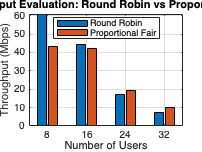

for i = 1:length(numUsersArray)   
    % Convert values from bps to Mbps
    allThroughputs(i).RoundRobin = allThroughputs(i).RoundRobin / 1e6; % Convert to Mbps
    allThroughputs(i).ProportionalFair = allThroughputs(i).ProportionalFair / 1e6; % Convert to Mbps
end

for i = 1:length(numUsersArray)
    rrThrouputs(i) = allThroughputs(i).RoundRobin;
    pfThrouputs(i) = allThroughputs(i).ProportionalFair;
end

% Create a grouped bar plot
figure; 
bar([rrThrouputs; pfThrouputs].'); 
set(gca, 'XTickLabel', numUsersArray); 
xlabel('Number of Users'); 
ylabel('Throughput (Mbps)'); 
title('Throughput Evaluation: Round Robin vs Proportional Fair'); 
legend({'Round Robin', 'Proportional Fair'}, 'Location', 'best'); 
grid on; 

## Plot Fairness index for each experiment

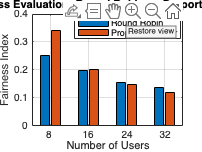

for i = 1:length(numUsersArray)
    rrFairness(i) = allFairness(i).RoundRobin;
    pfFairness(i) = allFairness(i).ProportionalFair;
end

% Create a grouped bar plot
figure; 
bar([rrFairness; pfFairness].'); 
set(gca, 'XTickLabel', numUsersArray); 
xlabel('Number of Users'); 
ylabel('Fairness Index'); 
title('Fairness Evaluation: Round Robin vs Proportional Fair'); 
legend({'Round Robin', 'Proportional Fair'}, 'Location', 'best'); 
grid on; 